fid=fopen('Comp_All_Scenario_S8.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);



ini_T = 19000

ind2 =      1     1     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0
     2     2     2     2     2     2     3     3     3     3
     6     6     6     6     6     6     6     6     6     6


Composicion =      9     9     8     8     8     8     9     9     9    10


Promedio_Nodos = 8.7000

ini_T = 22000

ind2 =     10    11    11    11    11    11    12    12    12    10
     2     2     2     2     2     2     2     2     2     2
     6     6     6     6     7     7     7     8     8     8
     7     6     6     6     7     7    10    10     9     8


Composicion =     25    25    25    25    27    27    31    32    31    28


Promedio_Nodos = 27.6000

ini_T = 29000

ind2 =      8     9    10    10    10     9     7     7     6     6
     0     1     1     1     1     1     1     1     1     1
    21    21    21    21    21    21    21    21    21    21
    10     9     8     9     9     9     9     9    10     9


Composicion =     39    40    40    41    41    40    38    38    38    37


Promedio_Nodos = 39.2000

ini_T = 30000

ind2 =     11    12    11    10     9     9    10    10     9     9
     2     3     3     3     3     3     3     3     3     3
    22    22    22    22    22    22    22    22    22    22
    12    14    14    15    15    15    14    14    14    14


Composicion =     47    51    50    50    49    49    49    49    48    48


Promedio_Nodos = 49

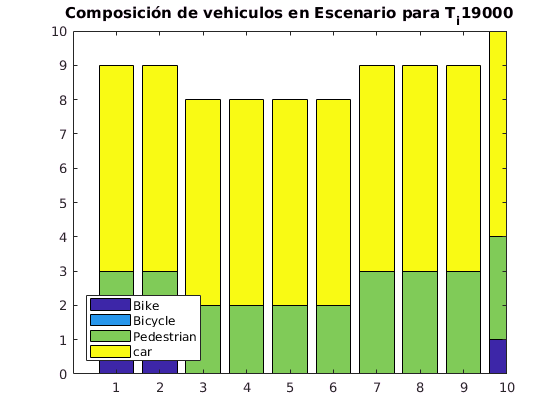

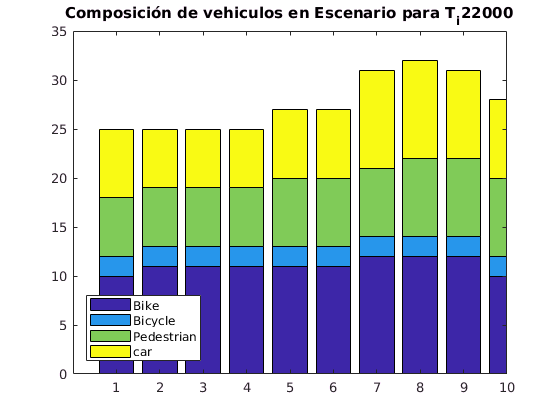

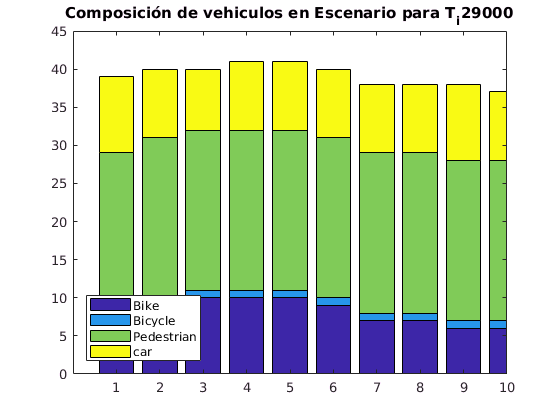

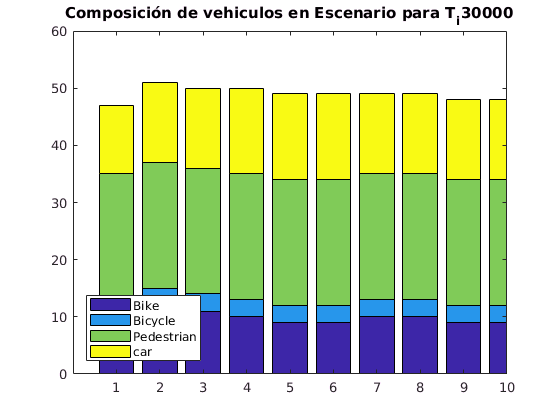

h=0;
for j=1:3:(length(tlines)-3)
h=h+1;
    %j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=20599s,22330s,22113s,23916s
ind2 = zeros(4,10);
ini_T = min(LD_Nodes(:,1));

for i=1:length(LD_Nodes(:,1))
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
  
end 

if h== 5 || h== 17 || h== 29 || h==  33
ini_T = min(LD_Nodes(:,1))
ind2
Composicion = sum(ind2)

Promedio_Nodos = mean(sum(ind2))

figure (j)
bar(ind2','stacked')
title(['Composición de vehiculos en Escenario para T_i',num2str(ini_T)])
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 10])
end 
end

%Buscar 
% 9 ->5 ,20,28,37 t=19000
% 25 -> 17    t= 22000
% 40 -> 29    t= 29000
% 50 - 33     t= 30000